clear
subject = "7916b";
data_pre = "iTBS-1_split_1.mat";
data_post = "iTBS-1_split_3.mat";

window_time = [-0.5,1];
[response_pre, avgresponse_pre, mainchans_pre] = extractEPs(subject,data_pre,window_time);
[response_post, avgresponse_post, mainchans_post] = extractEPs(subject,data_post,window_time);

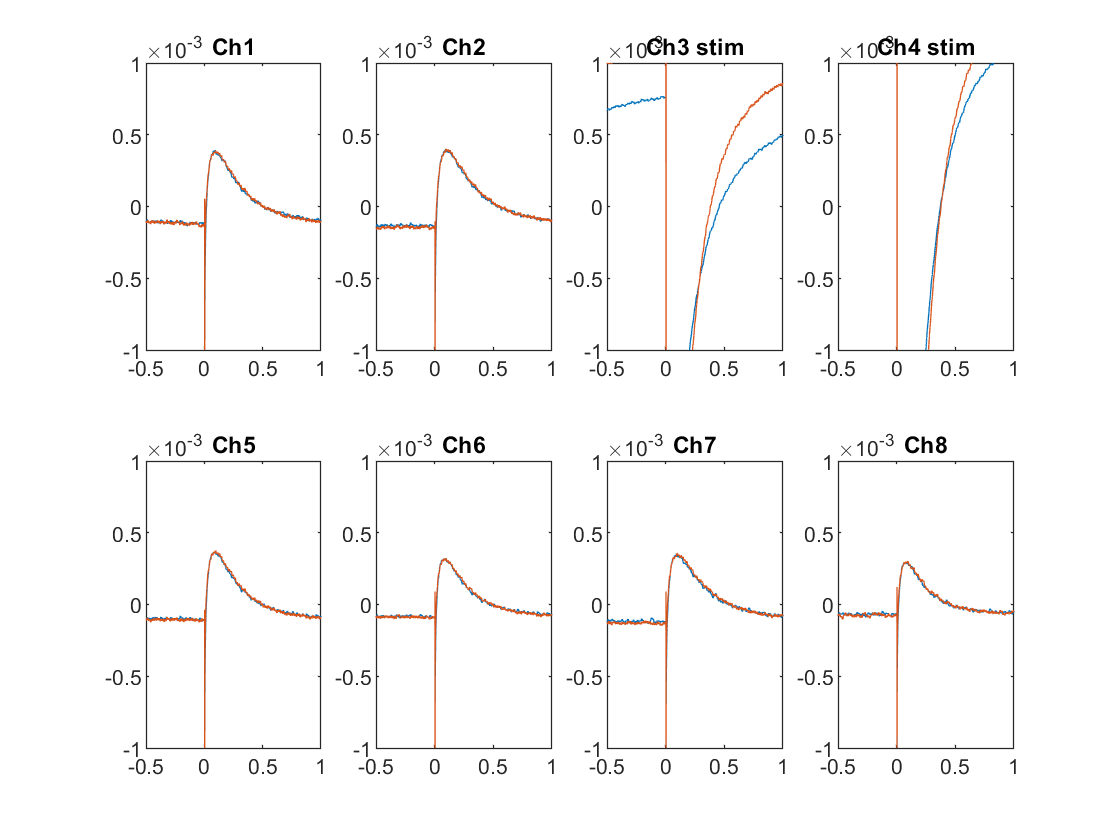

N_chan = size(avgresponse_pre,2);
N_pair = size(avgresponse_pre,1);
window_sz = length(avgresponse_pre);

for P_s=3%1:N_pair
    if P_s > 7
        C_s = P_s+1;
    else
        C_s = P_s;
    end
    
    f = figure;
    if N_chan > 8
        f.Position(3)=f.Position(3)*2;
    end
    
    for C_r=1:N_chan
        % subtract mean
        preEP = squeeze( avgresponse_pre(P_s,C_r,:) - mean(avgresponse_pre(P_s,C_r,:)) );
        postEP = squeeze( avgresponse_post(P_s,C_r,:) - mean(avgresponse_post(P_s,C_r,:)) );
        % plot pre vs post
        subplot(2,N_chan/2,C_r)
        plot(linspace(window_time(1),window_time(2),window_sz),preEP)
        hold on
        plot(linspace(-.5,1,window_sz),postEP)
        xlim([window_time(1), window_time(2)])
        ylim([-1e-3, 1e-3])
        if C_r == C_s || C_r == C_s+1
            title("Ch" + num2str(C_r) + " stim")
        else
            title("Ch" + num2str(C_r))
        end
    end
    
%     if C_s == mainchans_post(1)
%         saveas(gcf,"stim"+num2str(C_s)+"_"+num2str(C_s+1)+"main",'png')
%     else
%         saveas(gcf,"stim"+num2str(C_s)+"_"+num2str(C_s+1),'png')
%     end
end